B. Dado un arreglo X, ordenarlo de mayor a menor. El programa debera tambien crear un arreglo donde se guarden las posiciones iniciales de cada elemento. Obtener la media aritmetica del arreglo.

X = randi([0 100], 1, 10);
% Obtener el número de elementos en X
n = length(X);
% Imprimir el arreglo inicial
fprintf('X desordenado: ');

X desordenado: 

disp(X);

    15    98    96    49    80    14    42    92    80    96




% Crear un arreglo de índices inicializado con los valores de 1 a n
indices = 1:n;

% Ordenar X de mayor a menor sin usar la función sort
for i = 1:n-1
    for j = i+1:n
        if X(i) < X(j)
            % Intercambiar los valores en X
            temp = X(i);
            X(i) = X(j);
            X(j) = temp;
            
            % Intercambiar los índices correspondientes
            temp = indices(i);
            indices(i) = indices(j);
            indices(j) = temp;
        end
    end
end

% Obtener la media aritmética de X
media = mean(X);

% Imprimir los resultados
fprintf('X ordenado: ');

X ordenado: 

disp(X);

    98    96    96    92    80    80    49    42    15    14



fprintf('Índices: ');

Índices: 

disp(indices);

     2     3    10     8     9     5     4     7     1     6



fprintf('Media: %f\n', media);

Media: 66.200000


C. Graficar sin(t) y cos(t) de -pi a pi con diferentes colores

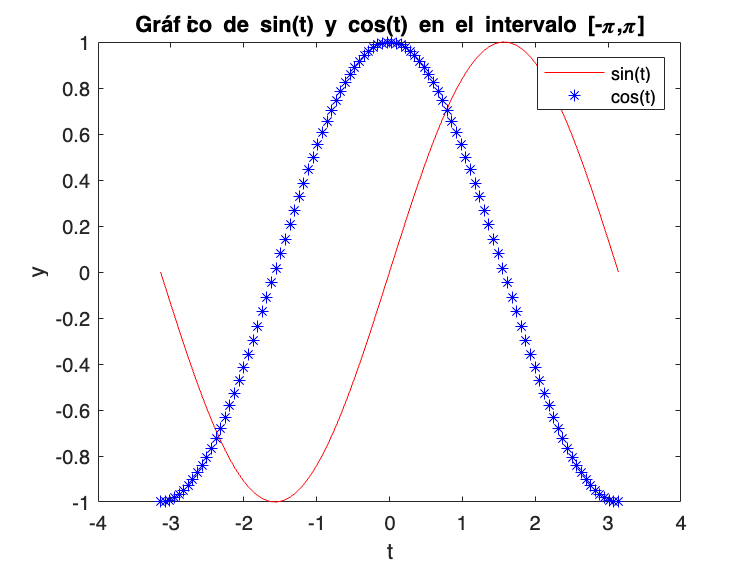

t = linspace(-pi, pi,100);   % Crear un vector con valores equiespaciados en el intervalo -pi a pi
y1 = sin(t);             % Evaluar la función sin(t) en el vector t
y2 = cos(t);             % Evaluar la función cos(t) en el vector t

figure;                  % Crear una nueva figura
plot(t, y1, 'r');        % Graficar la función sin(t) con color rojo
hold on;                 % Mantener la figura actual
plot(t, y2, 'b *');        % Graficar la función cos(t) con color azul
hold off;                % Liberar la figura

xlabel('t');             % Etiqueta del eje x
ylabel('y');             % Etiqueta del eje y
title('Gráfico de sin(t) y cos(t) en el intervalo [-\pi,\pi]');  % Título del gráfico
legend('sin(t)', 'cos(t)');  % Agregar leyenda